Plotting the function is a good idea to get an idea of where the roots are and provide initial guesses, then the methods can be used to get an accurate estimation. 

You can also substitute your answers back into the equation to see if it is correct (anonymous functions can help with that).

1. Use the **roots** function to find the roots of the polynomial.

%เรียงค่า x จากยกกำลังมากสุดไปน้อยสุด

root_sol = roots([1, 0, -10, 0, 21, 0])

root_sol =          0
   -2.6458
   -1.7321
    2.6458
    1.7321


disp(root_sol)

         0
   -2.6458
   -1.7321
    2.6458
    1.7321



2. Create an anonymous function for p(x) and substitute the roots you found in question 1 into it to verify your answer.

p = @(x) x^5 - 10*(x^3) + 21*x

p = function_handle with value:
    @(x)x^5-10*(x^3)+21*x


sol = []


sol =

     []




for n = 1:length(root_sol)
    sol(end + 1) = p(root_sol(n))
end

sol = 0

sol = 1.0e-12 *

         0   -0.1705


sol = 1.0e-12 *

         0   -0.1705   -0.0568


sol = 1.0e-12 *

         0   -0.1705   -0.0568   -0.0995


sol = 1.0e-12 *

         0   -0.1705   -0.0568   -0.0995    0.0142


disp(sol)

   1.0e-12 *

         0   -0.1705   -0.0568   -0.0995    0.0142



3. Use the **roots** function to find the roots of the polynomial (no template). Display only the real roots.

% imag function is used to extract the imaginary parts of the roots. The real roots are the ones where the imaginary parts are equal to 0

q = @(x) -2*(x^6) - 1.5*(x^4) + 10*x + 2

q = function_handle with value:
    @(x)-2*(x^6)-1.5*(x^4)+10*x+2



coefficient = [-2, 0, -1.5, 0, 0, 10, 2]

coefficient =    -2.0000         0   -1.5000         0         0   10.0000    2.0000



roots_sol = roots(coefficient)

roots_sol =    1.3213 + 0.0000i
   0.4201 + 1.4191i
   0.4201 - 1.4191i
  -0.9809 + 0.8761i
  -0.9809 - 0.8761i
  -0.1997 + 0.0000i



% Filter out the real roots
real_roots = roots_sol(imag(roots_sol) == 0);

4. Use the **fzero** function to locate all roots of

on the interval [0,5]. Plot the function with a grid and mark the roots with large green diamonds. For this question make a function file to hold the function. You will have to divide the interval into pieces using an appropriate step size, h. First try 

h = 2, then plot the function and roots to see if it found them all. If not, adjust your value of h and try again.

x_range = linspace(0, 5, 100)

x_range =          0    0.0505    0.1010    0.1515    0.2020    0.2525    0.3030    0.3535    0.4040    0.4545    0.5051    0.5556    0.6061    0.6566    0.7071    0.7576    0.8081    0.8586    0.9091    0.9596    1.0101    1.0606    1.1111    1.1616    1.2121    1.2626    1.3131    1.3636    1.4141    1.4646    1.5152    1.5657    1.6162    1.6667    1.7172    1.7677    1.8182    1.8687    1.9192    1.9697    2.0202    2.0707    2.1212    2.1717    2.2222    2.2727    2.3232    2.3737    2.4242    2.4747


y_range = myFunction(x_range)

y_range =    -1.0000   -0.9509   -0.9050   -0.8629   -0.8254   -0.7931   -0.7666   -0.7466   -0.7336   -0.7282   -0.7309   -0.7419   -0.7616   -0.7903   -0.8278   -0.8741   -0.9291   -0.9922   -1.0629   -1.1403   -1.2235   -1.3112   -1.4021   -1.4942   -1.5859   -1.6748   -1.7586   -1.8346   -1.8999   -1.9514   -1.9859   -1.9999   -1.9896   -1.9515   -1.8815   -1.7759   -1.6306   -1.4418   -1.2057   -0.9186   -0.5770   -0.1778    0.2819    0.8047    1.3924    2.0466    2.7681    3.5571    4.4130    5.3345



roots_sol =

     []



root = 2.0911

root = 2.0911

root = 4.5678


roots_sol =

     []



root = 2.0911

root = 2.0911


roots_sol =

     []



root = 2.0911

root = 4.5678

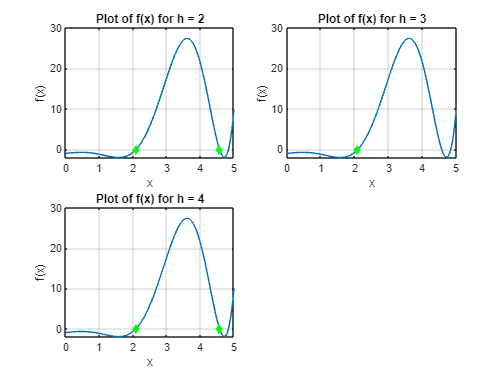


for h = 2:4
    roots_sol = []

    for x = 0 : h : 5
        root = fzero(@myFunction, x)

        % Check if the root is within the current subinterval
        if root >= x && root <= x + h
            % Add the root to the array
            roots_sol = [roots_sol, root];
        end
    end
    % do many grids
    subplot(2, 2, h-1)

    % find the real roots
    real_roots = roots_sol(imag(roots_sol) == 0);
    plot(x_range, y_range)

    xlabel('x');
    ylabel('f(x)');
    title(['Plot of f(x) for h = ', num2str(h)]);
    grid on
    hold on

    % Mark the roots with green diamonds
    plot(real_roots, myFunction(real_roots), 'gd', 'MarkerSize', 5, 'MarkerFaceColor', 'g');
    
    xlim([0,5])
end

using Fixed Point Iteration. Choose your own stopping criteria and keep track of the error at each iteration. Keep in mind that you can choose any of the following 4 formulas for your fixed point iteration:

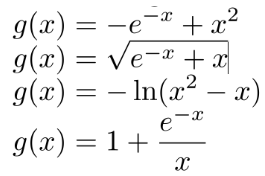

Test all of them to see which work and which don’t. 

Formula 1 did not converge within 100 iterations.


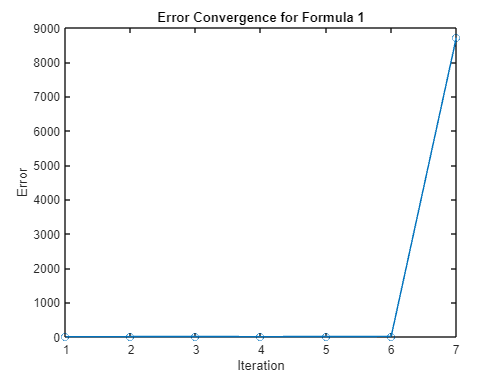

Formula 2 converged after 11 iterations: x = 1.235346


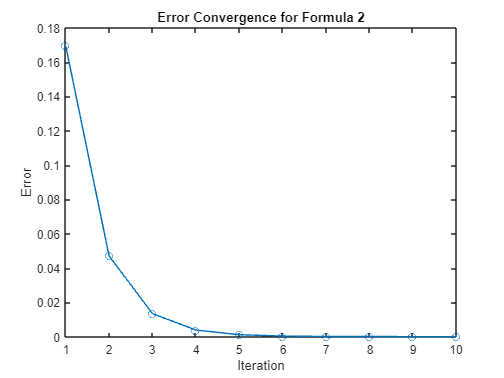

Formula 3 did not converge within 100 iterations.


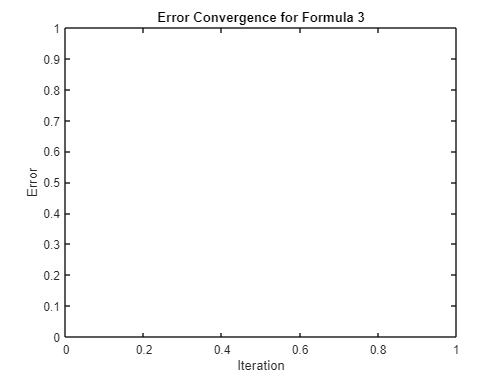

Formula 4 converged after 17 iterations: x = 1.235346


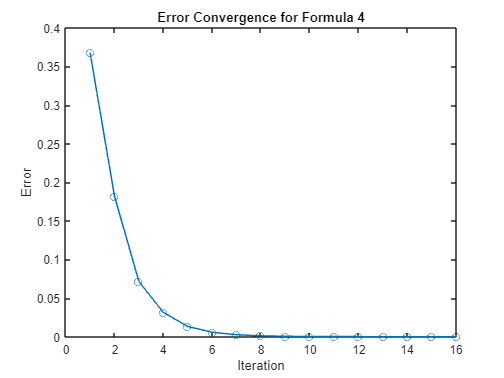

% Define the function h(x)
h = @(x) x.^2 - x - exp(-x);

% Initial guess and tolerance
x0 = 1;
tolerance = 1e-6;

% Initialize variables to store results
max_iterations = 100;
error_history = zeros(max_iterations, 1);

% Formulas for fixed-point iteration
formulas = {@(x) -exp(-x) + x.^2;
            @(x) sqrt(exp(-x) + x);
            @(x) -log(x.^2 - x);
            @(x) 1 + exp(-x)./x};

% Iterate over each formula
for formula_index = 1:numel(formulas)
    formula = formulas{formula_index};
    x = x0;
    iterations = 1;
    error_list = [];
    
    while iterations <= max_iterations
        x_new = formula(x);
        error = abs(x_new - x);
        
        % Check the stopping criteria
        if error <= tolerance
            fprintf('Formula %d converged after %d iterations: x = %.6f\n', formula_index, iterations, x_new);
            break;
        end
        
        error_list(end+1) = error;
        x = x_new;
        iterations = iterations + 1;
    end
    
    if iterations > max_iterations
        fprintf('Formula %d did not converge within %d iterations.\n', formula_index, max_iterations);
    end
    
    % Plot error convergence for each formula
    figure;
    plot(1:numel(error_list), error_list, '-o');
    title(sprintf('Error Convergence for Formula %d', formula_index));
    xlabel('Iteration');
    ylabel('Error');
end

6. Write a function that takes an initial guess as input then locates a root of 

using the Newton-Raphson Method. Remember you will have to differentiate the function to get the formula. Choose your own convergence criterion.

syms x
r = sin(x) * cos(2*x)

$$r = \cos\left(2\,x\right)\,\sin\left(x\right)$$

diff_r = diff(r)

$$diff\_r = \cos\left(2\,x\right)\,\cos\left(x\right)-2\,\sin\left(2\,x\right)\,\sin\left(x\right)$$

newtonRaphson(5, r, diff_r, 0.000001)

ans = 5.4978

7. Use your function from question 7 to find all roots of r(x) on the interval [–π,π].

%all_roots = []
%for x = -pi:pi
%    root = newtonRaphson(1, r, diff_r, 0.000001)
%    if root == all_roots(end)
%        continue;
%    else
%        all_roots(end+1) = root
%    end
%end
%disp(all_roots)

8. Write a script that locates all roots of 

using the Bisection Method. Locate brackets by using the incremental search method you wrote before.

% Define the function w(x)
w = @(x) x^3 - 6*x^2 + 10*x - 4;

% Define the search interval [a, b]
a = -10; % Start with a wide interval
b = 10;
step = 0.01; % Incremental search step size

% Initialize variables
roots = []; % To store the roots
found_exact_root = false;

% Perform incremental search to locate brackets and check for exact roots
while a <= b
    if w(a) == 0
        roots = [roots, a];
        found_exact_root = true;
    elseif w(a) * w(a + step) < 0
        % Bracket found, apply Bisection method
        [root, ~] = bisection(w, a, a + step, 1e-8);
        roots = [roots, root];
    end
    
    a = a + step;
end

% Display whether an exact root was found
if found_exact_root
    disp('A root was found by the incremental search method.');
else
    disp('No exact root was found by the incremental search method.');
end

No exact root was found by the incremental search method.


% Display the roots found by the Bisection method
fprintf('The roots are:\n');

The roots are:


fprintf('root = %.4f ', roots);

root = 0.5858 root = 2.0000 root = 3.4142 

9. The volume of liquid V in a hollow horizontal cylinder of radius r and length L is related to the depth of the liquid h by,

% acos = cos^-1, same with other sin and tan, put a infront
% cube_root = nthroot(x, 3); x = the number u want to put in the root
% Given values
r = 2;    % radius in meters
L = 5;    % length in meters
V = 8;    % volume in cubic meters

% Define the equation in terms of h
equation = @(h) (r^2 * acos((r - h) / r) - (r - h) * sqrt(2 * r * h - h^2)) * L - V;

% Use numerical solver to find h
initial_guess = 1; % Initial guess for h
h = fzero(equation, initial_guess);

% Display the result
disp('h = ');

h = 


disp(h);

    0.7400



10. Determine the location of the horizontal tangents (turning points) of

on the interval [–π,π]. Plot the figure and mark the turning points with thick, large red circles with blue faces 

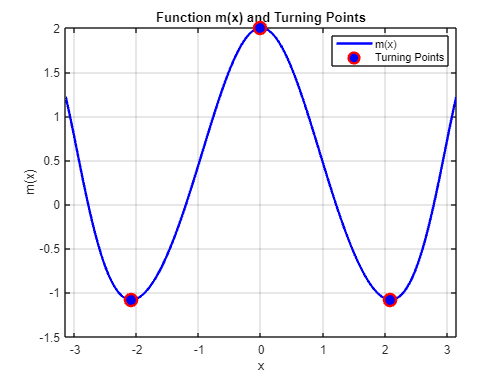

% Step 1: Create a range of x-values
x = linspace(-pi, pi, 1000);

% Define the function m(x)
m = cos(x.^2/2) + cos(2*x);

% Step 2: Calculate the derivative of m(x)
dm_dx = diff(m)./diff(x);

% Step 3: Find the x-values where the derivative is approximately zero
x_tangent = x(1:end-1) + diff(x)/2; % Use midpoints of intervals
x_turning_points = x_tangent(abs(dm_dx) < 0.01); % Tolerance can be adjusted

% Step 4: Calculate corresponding y-values
y_turning_points = cos(x_turning_points.^2/2) + cos(2*x_turning_points);

% Step 5: Plot the function and mark turning points
figure;
plot(x, m, 'b', 'LineWidth', 2);
hold on;
plot(x_turning_points, y_turning_points, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'b', 'LineWidth', 2);
title('Function m(x) and Turning Points');
xlabel('x');
ylabel('m(x)');
grid on;
xlim([-pi, pi]);

% Display legend
legend({'m(x)', 'Turning Points'}, 'Location', 'Best');

% Show the plot
hold off;

function [root, n] = bisection(func, a, b, tolerance)
    n = 0;
    while (b - a) / 2 > tolerance
        midpoint = (a + b) / 2;
        if func(midpoint) == 0
            root = midpoint;
            return;
        elseif func(a) * func(midpoint) < 0
            b = midpoint;
        else
            a = midpoint;
        end
        n = n + 1;
    end
    root = (a + b) / 2;
end

% xi = initial guess
% fx = function
% fprimex = diff func
% maxTol = max tolerance

function aOut = newtonRaphson(xi, fx, fPrimeX, maxTol)
    x1 = xi;
    xBef = 0;
    delta = 10000;
    while delta > maxTol
        xBef = x1;
        x = x1;
        x1 = x1 - (double(subs(fx))/double(subs(fPrimeX)));
        delta = abs(x1 - xBef);
    end
    aOut = x1;
end